# Aula Pratica I 

## 1. Para um sinal x(t) = cos(2πft) com duração de 5 s e frequência de amostragem fs = 44.1 kHz faça o que se pede nos itens abaixo:

a)Gere gráficos de x(t) no domÍnio tempo para f ∈{500, 5000, 10000} Hz.

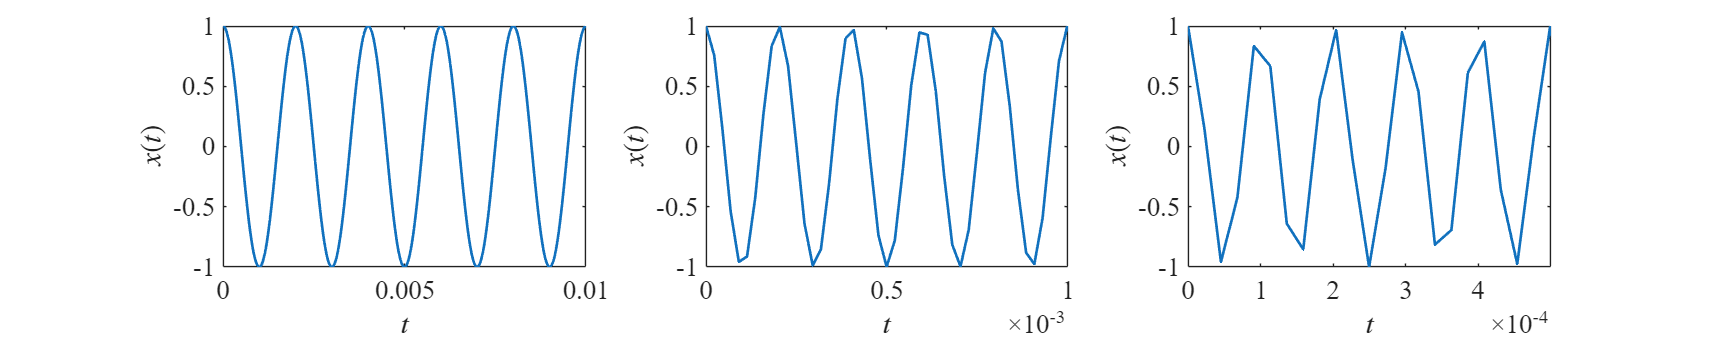

Ts = 1/44100;               % ou Ts = 1e-3;
t  = 0:Ts:5;             % Definindo o tempo
f=500;
pt=0;
zoom=0.01;
x  = cos(2*pi*f*t); % x(t)
subplot(1,3,1);
plota(t,x,0,3000);


xlim([pt pt+zoom])
ylim([-1.00 1.00])
zlim([-1.00 1.00])
 
ax = gca;
chart = ax.Children(1);
datatip(chart,2.795,-0.5721);
zoom=0.001;
f=5000;
x  = cos(2*pi*f*t);

subplot(1,3,2);
plota(t,x,0,3000);

xlim([pt pt+zoom])
ylim([-1.00 1.00])
zlim([-1.00 1.00])

zoom=0.0005;
f=10000;
x  = cos(2*pi*f*t);
subplot(1,3,3);
plota(t,x,0,3000);

xlim([pt pt+zoom])
ylim([-1.00 1.00])
zlim([-1.00 1.00])
 
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,4.64,0.8713);

b) Utilizando a função spectrumAnalyzer(), calcule a resposta em frequência (espectro) dos sinais.

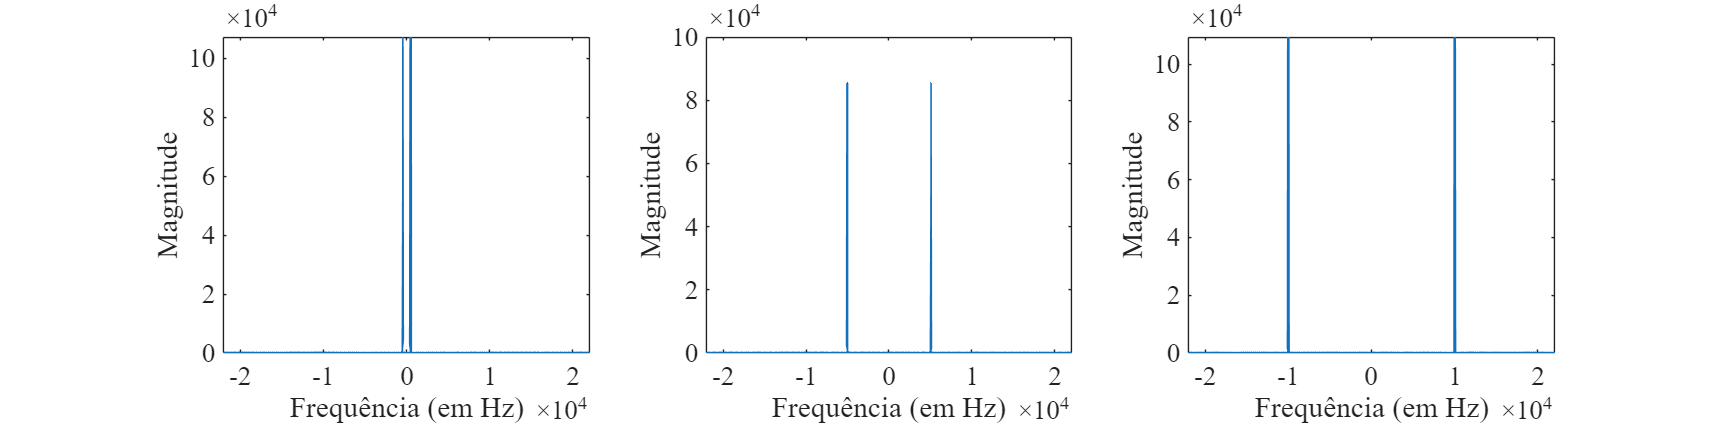

Ts = 1/44100;
t  = 0:Ts:5;
f  = 500;
lar=2400;
figure;
x = cos(2*pi*f*t);
subplot(1,3,1);
fs = 1/Ts;
spectrumAnalyzermod(x,fs,0,lar);
%--------------------%
f  = 5000;
x = cos(2*pi*f*t);
subplot(1,3,2);
spectrumAnalyzermod(x,fs,0,lar);
%--------------------%
f  = 10000;
x = cos(2*pi*f*t);
subplot(1,3,3);
spectrumAnalyzermod(x,fs,0,lar);

c) Utilizando o comando sound(), ouça os sinais

Ts = 1/44100;               % ou Ts = 1e-3;
t  = 0:Ts:5;             % Definindo o tempo
fs=1/Ts;

x1= cos(2*pi*500*t) ; 
x2= cos(2*pi*5000*t) ; 
x3= cos(2*pi*10000*t) ; 

sound(x1,fs);
pause(6);

sound(x2,fs);
pause(6)

sound(x3,fs);





## 2.Para um chirp com frequência inicial f0 = 500 Hz, frequência final f1 = 10000 Hz, duraçâo de 5 s e frequência de amostragem fs = 44.1 kHz faça o que se pede nos itens abaixo:

a) Gere gráficos de chirps no domínio do tempo com varredura de frequência linear, quadrática e logarítmica.

fs = 44100;         % frequência de amostragem
t = 0:1/fs:5;       % vetor de tempo (5 segundos)
f0 = 500;           % frequência inicial (Hz)
f1 = 10000;          % frequência final (Hz)
z=3.8;%3.8;
g=0.1;%0.1;
zv=4;
x1 = chirp(t,f0,5,f1);
x2 = chirp(t,f0,5,f1,"quadratic");
x3 = chirp(t,f0,5,f1,'logarithmic');

figure;
%plota(t,x1);
subplot(1,3,1);
spectro(fs,x1,'Chirp Linear',0,0);

%xlim([z z+g])
%ylim([-zv zv])


subplot(1,3,2);
spectro(fs,x2,'Chirp Quadrático',0,0);
%xlim([z z+g])
%ylim([-zv zv])

subplot(1,3,3);
spectro(fs,x3,'Chirp Logaritimico',0,0);
figure;
subplot(1,3,1);
plota(t,x1,0,3000);
xlim([z z+g])
ylim([-zv zv])

subplot(1,3,2);

plota(t,x2,0,3000);
xlim([z z+g])
ylim([-zv zv])

subplot(1,3,3);

plota(t,x3,0,3000);
xlim([z z+g])
ylim([-zv zv])

b) Utilizando a função spectrumAnalyzer(), calcule a resposta em frequência (espectro) dos chirps.

fs = 44100;         % frequência de amostragem
t = 0:1/fs:5;       % vetor de tempo (5 segundos)

f0 = 500;           % frequência inicial (Hz)
f1 = 10000;          % frequência final (Hz)
lar=2400;

x1 = chirp(t,f0,5,f1);
x2 = chirp(t,f0,5,f1,"quadratic");
x3 = chirp(t,f0,5,f1,'logarithmic');

figure;
subplot(1,3,1);
spectrumAnalyzermod(x1,fs,0,lar);
%--------------------%
subplot(1,3,2);
spectrumAnalyzermod(x2,fs,0,lar);
%--------------------%
subplot(1,3,3);
spectrumAnalyzermod(x3,fs,0,lar);

c) Utilizando o comando sound(), ouça os chirps.

fs = 44100;         % frequência de amostragem
t = 0:1/fs:5;       % vetor de tempo (5 segundos)

f0 = 500;           % frequência inicial (Hz)
f1 = 10000;          % frequência final (Hz)


x1 = chirp(t,f0,5,f1);
x2 = chirp(t,f0,5,f1,"quadratic");
x3 = chirp(t,f0,5,f1,'logarithmic');

sound(x1,fs);
pause(6);
sound(x2,fs);
pause(6);
sound(x3,fs);


## 3.Utilizando o comando load(), leia o arquivo handel.mat e faça o que se pede nos itens abaixo: 

a) Gere um gráfico do sinal de aúdio no domínio do

tempo.

load handel.mat
Ts = 1/Fs;
t=(1:length(y))/Fs;

plota(t,y,1,800);

b) Utilizando a função spectrumAnalyzer(), calcule a resposta em frequência (espectro) do sinal de áudio.

load handel.mat
Ts = 1/Fs;               % ou Ts = 1e-3; 
t=(1:length(y))/Fs;% Definindo o tempo

spectrumAnalyzer(y,Fs);

c) Utilizando o comando sound(), ouça o sinal de

áudio com a frequência de amostragem original do sinal

original, com o dobro da frequência original e o quádruplo

da frequência original.

load('handel.mat');
%load handel.mat
fne=[Fs 2*Fs 4*Fs];

sound(y,fne(1));
pause(9);
sound(y,fne(2));
pause(5);
sound(y,fne(3));

## 4. Para o arquivo de áudio da questão anterior, faça o que se pede nos itens abaixo: 

a) Utilizando o comando upsample(), realize uma sobreamostragem do sinal de áudio de um fator de M ∈ {2, 4, 8}. Em seguida, avalie o espectro dos sinais 

load handel.mat;
% Ts = 1/Fs;
lar=2400;
y1=upsample(y,2);
y2=upsample(y,4);
y3=upsample(y,8);
fne=[2*Fs 4*Fs 8*Fs];

figure;
subplot(1,3,1);
spectrumAnalyzermod(y1,fne(1),0,lar);
%--------------------%
subplot(1,3,2);
spectrumAnalyzermod(y2,fne(2),0,lar);
%--------------------%
subplot(1,3,3);
spectrumAnalyzermod(y3,fne(3),0,lar);
sound(y1,fne(1));
pause(9);
sound(y2,fne(2));
pause(9);
sound(y3,fne(3));


b) Repita o item anterior utilizando o comando resample().

load handel.mat;
% Ts = 1/Fs;
lar=2400;
y1=resample(y,2,1);
y2=resample(y,4,1);
y3=resample(y,8,1);
fne=[2*Fs 4*Fs 8*Fs];

figure;
subplot(1,3,1);
spectrumAnalyzermod(y1,fne(1),0,lar);
%--------------------%
subplot(1,3,2);
spectrumAnalyzermod(y2,fne(2),0,lar);
%--------------------%
subplot(1,3,3);
spectrumAnalyzermod(y3,fne(3),0,lar);
sound(y1,fne(1));
pause(9);
sound(y2,fne(2));
pause(9);
sound(y3,fne(3));

c) Utilizando o comando downsample(), realize uma subamostragem do sinal de áudio de um fator de M ∈ {2, 4, 8}. Em seguida, avalie o espectro dos sinais subamostrados  ouça os sinais subamostrados. 

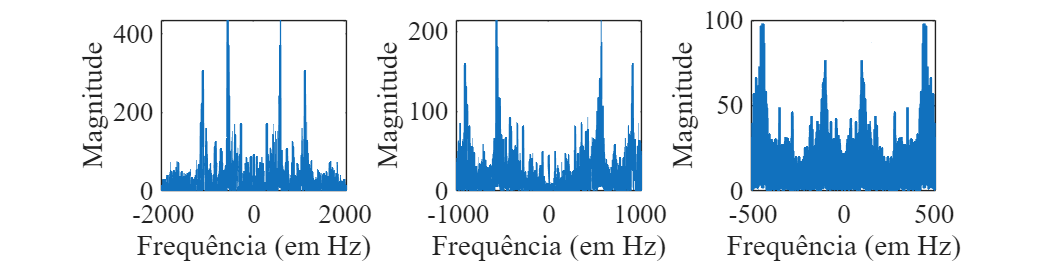

load handel.mat;
% Ts = 1/Fs;
lar=2400;
y1=downsample(y,2);
y2=downsample(y,4);
y3=downsample(y,8);
fne=[Fs/2 Fs/4 Fs/8];

figure;
subplot(1,3,1);
spectrumAnalyzermod(y1,fne(1),0,lar);
%--------------------%
subplot(1,3,2);
spectrumAnalyzermod(y2,fne(2),0,lar);
%--------------------%
subplot(1,3,3);
spectrumAnalyzermod(y3,fne(3),0,lar);

sound(y1,fne(1));
pause(9);
sound(y2,fne(2));
pause(9);
sound(y3,fne(3));

d) Repita o item anterior utilizando o comando resample().

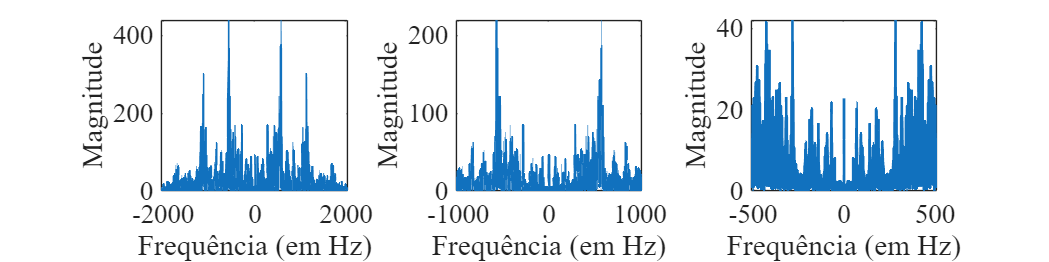

load handel.mat;
% Ts = 1/Fs;
lar=2400;
y1=resample(y,1,2);
y2=resample(y,1,4);
y3=resample(y,1,8);
fne=[Fs/2 Fs/4 Fs/8];

figure;
subplot(1,3,1);
spectrumAnalyzermod(y1,fne(1),0,lar);
%--------------------%
subplot(1,3,2);
spectrumAnalyzermod(y2,fne(2),0,lar);
%--------------------%
subplot(1,3,3);
spectrumAnalyzermod(y3,fne(3),0,lar);

sound(y1,fne(1));
pause(9);
sound(y2,fne(2));
pause(9);
sound(y3,fne(3));



## 6. Utilizando o comando audioread(), leia os arquivos h_banheiro.wav, sinal_taca.wav e faça o que se pede nos itens abaixo:

a) Gere um gráfico dos sinais no domínio do tempo. 

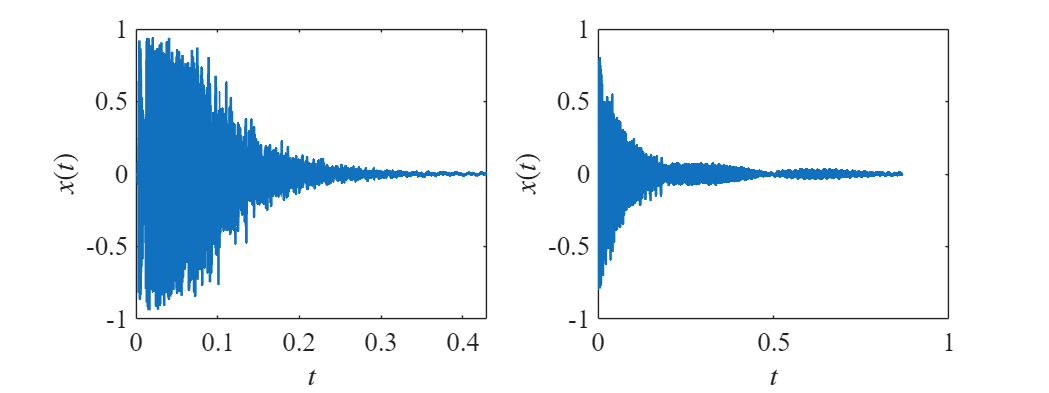

[y1, Fs1]=audioread('h_banheiro.wav');
[y2,Fs2]=audioread('sinal_taca.wav');  
figure;
lar=1600;
t1=(1:length(y1))/Fs1;% Definindo o tempo
t2=(1:length(y2))/Fs2;% Definindo o tempo
subplot(1,2,1);
plota(t1,y1,0,lar);            
subplot(1,2,2);
plota(t2,y2,0,lar);

b)Utilizando a função spectrumAnalyzer(), calcule a resposta em frequência (espectro) dos sinais.

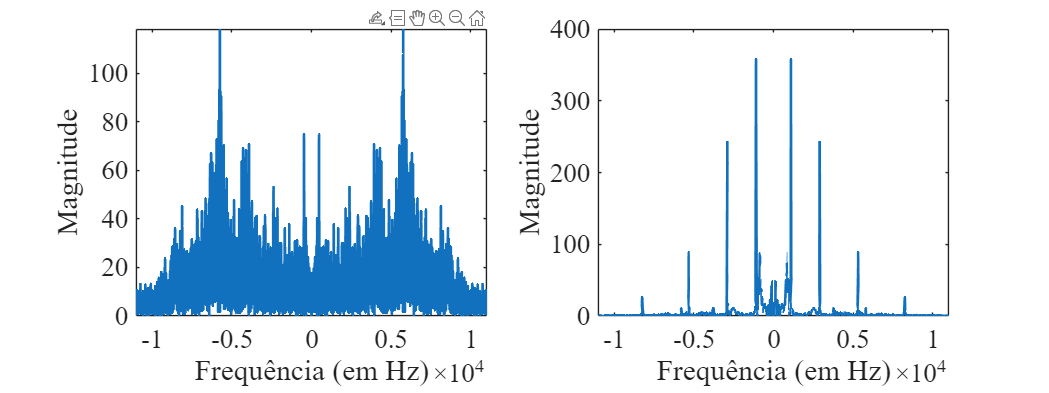

[y1, Fs1]=audioread('h_banheiro.wav');
[y2,Fs2]=audioread('sinal_taca.wav'); 
lar=1600;
figure;
t1=(1:length(y1))/Fs1;% Definindo o tempo
t2=(1:length(y2))/Fs2;% Definindo o tempo
subplot(1,2,1);
spectrumAnalyzermod(y1,Fs1,0,lar);
%--------------------%
subplot(1,2,2);
spectrumAnalyzermod(y2,Fs2,0,lar);

c)Utilizando o comando sound(), ouça os sinais.

[y1, Fs1]=audioread('h_banheiro.wav');
[y2,Fs2]=audioread('sinal_taca.wav'); 


sound(y1,Fs1);
pause(1);
sound(y2,Fs2);


## 7. Utilizando o comando conv(), calcule a resposta de hbanheiro[n] para uma entrada igual ao sinal de áudio e o sinal da taça. Note que essa operação equivale ao sinal de áudio e ao sinal da taça se propagando em ambiente modelado pela resposta ao impulso hbanheiro[n]. 

a)Avalie as respostas no tempo.

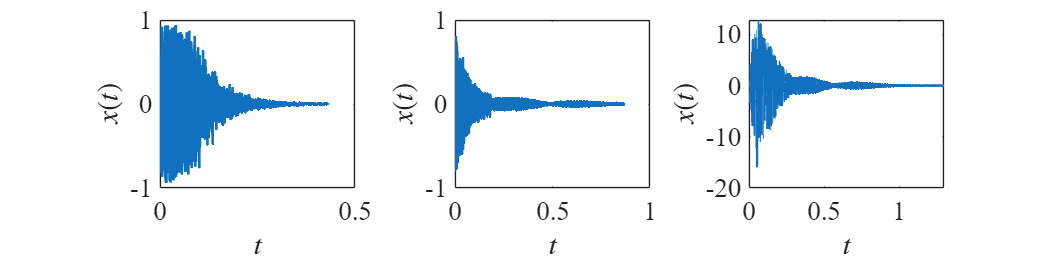

[y1, Fs1]=audioread('h_banheiro.wav');
[y2,Fs2]=audioread('sinal_taca.wav'); 
lar=2400;
Fs=Fs1; %Fs1 e Fs2 são iguais
figure;
t1=(1:length(y1))/Fs;% Definindo o tempo
t2=(1:length(y2))/Fs;% Definindo o tempo%
h=conv(y1,y2);
th=(1:length(h))/Fs;



subplot(1,3,1);
plota(t1,y1,0,lar);            
subplot(1,3,2);
plota(t2,y2,0,lar);
subplot(1,3,3);
plota(th,h,0,lar);

b)Avalie as respostas na frequência.

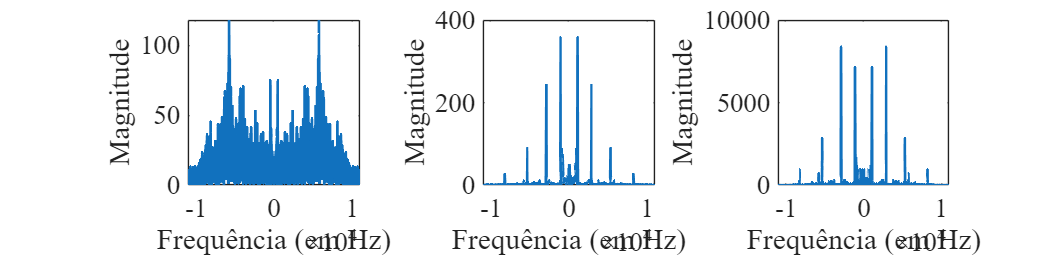

[y1, Fs1]=audioread('h_banheiro.wav');
[y2,Fs2]=audioread('sinal_taca.wav'); 
lar=2400;
Fs=Fs1; %Fs1 e Fs2 são iguais
figure;

h=conv(y1,y2);


subplot(1,3,1);
spectrumAnalyzermod(y1,Fs,0,lar);
%--------------------%
subplot(1,3,2);
spectrumAnalyzermod(y2,Fs,0,lar);
%--------------------%
subplot(1,3,3);
spectrumAnalyzermod(h,Fs,0,lar);

c) Ouça as respostas.

[y1, Fs1]=audioread('h_banheiro.wav');
[y2,Fs2]=audioread('sinal_taca.wav'); 
Fs=Fs1;
h=conv(y1,y2);

sound(y1,Fs);
pause(1);
sound(y2,Fs);
pause(1);
sound(h,Fs);